We consider the IVP $u'=\sin[(u+t)^2]$ over $0\le t \le 4$, with $u(0)=-1$. 

f = @(t,u) sin( (t+u).^2 );
a = 0;  b = 4;
u0 = -1;

We use the built-in solver `ode113` to construct an accurate approximation to the exact solution.

opt = odeset('abstol',5e-14,'reltol',5e-14); 
uhat = ode113(f,[a,b],u0,opt);
u_exact = @(t) deval(uhat,t)';  % callable function

Now we perform a convergence study of the AB4 code. 

n = 10*2.^(0:5)';
err = 0*n;
for j = 1:length(n)
    [t,u] = ab4(f,[a,b],u0,n(j));
    err(j) = max(abs(u_exact(t)-u));
end

The method should converge as $O(h^4)$, so a log-log scale is appropriate for the errors. 

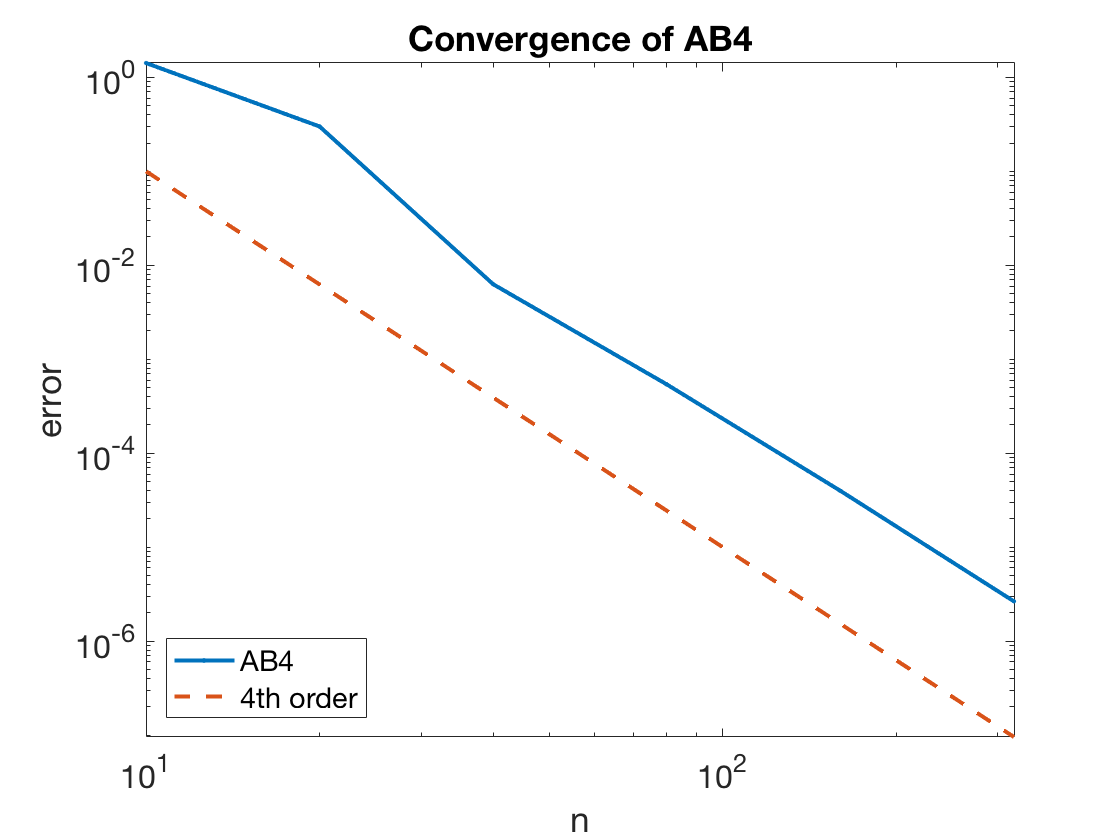

loglog(n,err,'.-')
xlabel('n'), ylabel('error')  % ignore this line
title('Convergence of AB4')   % ignore this line
hold on, loglog(n,0.1*(n/n(1)).^(-4),'--')
axis tight   % ignore this line
legend('AB4','4th order','location','southwest')   % ignore this line